clear variables
rng(1);

%parameters
tmax = 100;
n = 2;
nres = 1;

c = [1; .49]

c =     1.0000
    0.4900


d = [.2; .1];
I = 1;
E = .1;
gamma = d(1) / c(1)

gamma = 0.2000

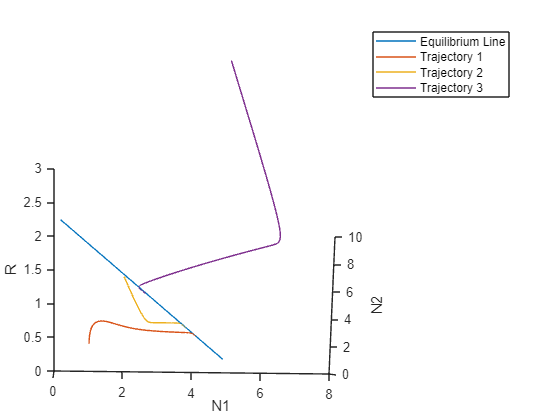


state0 = [1;1;.2];
state1 = [2;2;1];
state2 = [5;8;3];

%simulate
tspan = [0 tmax];
[t,y] = ode45(@(t,state0) f(state0,c,I,E,d,n,nres), tspan, state0);
[t1,y1] = ode45(@(t,state0) f(state0,c,I,E,d,n,nres), tspan, state1);
[t2,y2] = ode45(@(t,state0) f(state0,c,I,E,d,n,nres), tspan, state2);

b = 0:.1:10;
a = (I - E * gamma) / (c(1) * gamma) - (c(2)/c(1)) * b;
c = linspace(.2,.2,length(a));

plot3(a,b,c)
hold on
plot3(y(:,1), y(:,2), y(:,3))
plot3(y1(:,1), y1(:,2), y1(:,3))
plot3(y2(:,1), y2(:,2), y2(:,3))
legend('Equilibrium Line','Trajectory 1','Trajectory 2','Trajectory 3');
xlabel('N1') 
ylabel('N2') 
zlabel('R')

function dState = f(state,affinities,I,E,death,n,nres)
    dState = zeros(n+nres,1);
    N = state(1:n);
    R = state(n+1:n+nres);
    dN = (affinities * R - death) .* N;
    dR = I - E .* R - affinities.' * N .* R;
    dState(1:n) = dN;
    dState(n+1:n+nres) = dR;
end